# Vein Detector

## Parameters

smooth = 0.5;
resize = [512, 512];
threshold = 0;
method = "canny";

## Select images

[baseName, folder] = uigetfile('*.png', 'MultiSelect', 'on');

images = cell(size(baseName));

for i = 1:numel(baseName)
    fullFileName = fullfile(folder, baseName{i})
    images{i} = imread(fullFileName);
end

fullFileName = '/Users/kevinhuestis/Development/vein-detector/images/out196_180.png'

fullFileName = '/Users/kevinhuestis/Development/vein-detector/images/out222_180.png'

fullFileName = '/Users/kevinhuestis/Development/vein-detector/images/out228_180.png'

fullFileName = '/Users/kevinhuestis/Development/vein-detector/images/out239_200.png'

## Preprocessing

prcd_ims = cell(size(images));

for i = 1:numel(images)
    im = images{i};
    
    % Smoothing
    im_smooth = imgaussfilt(im, smooth);
    
    % Resizing (256x256)
    im_resized = imresize(im_smooth, resize);
    
    % Histogram Equalization
    im_histeq = histeq(im_resized);
    
    % Convert
    im_gray = rgb2gray(im_histeq);
    
    % Remove background
    foreground = im_gray > threshold;
    fore_smooth = imclose(foreground, strel('disk', 3));
    
    % Crop
    im_crop = im_gray .* uint8(fore_smooth);
    
    % Save to cell array
    prcd_ims{i} = im_crop;
end

## Line Detection

#### Basic Algorithm

line_array = cell(size(prcd_ims));

for i = 1:numel(prcd_ims)
    im = prcd_ims{i};
    
    switch lower(method)
        case 'sobel'
            lines = edge(im,'sobel');
        case 'prewitt'
            lines = edge(im,'prewitt');
        case 'roberts'
            lines = edge(im,'roberts');
        case 'log'
            lines = edge(im,'log');
        case 'zerocross'
            lines = edge(im,'zerocross');
        case 'canny'
            lines = edge(im,'canny');
%             lines = edge(im,'canny',[0.005 0.05]);
        case 'approxcanny'
            lines = edge(im,'approxcanny');
        otherwise
            throw("Invalid line detection method given.")
    end
    
    line_array{i} = lines;
end

#### Visualize

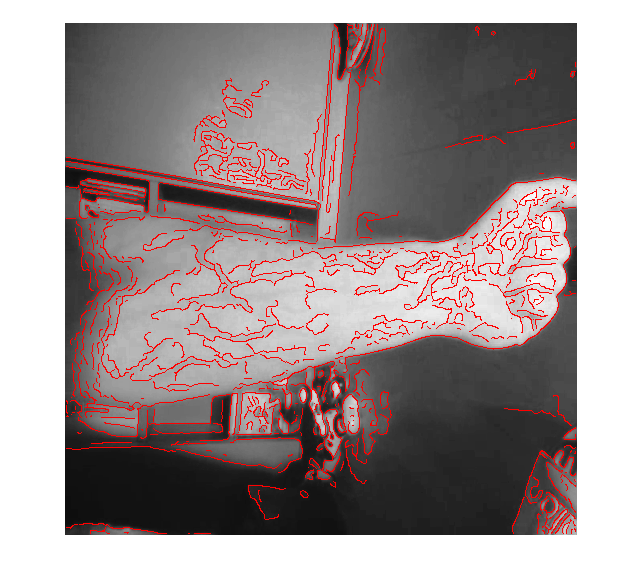

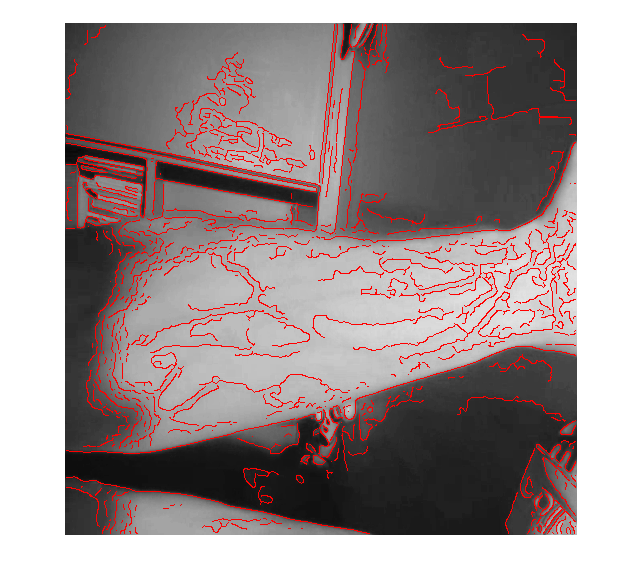

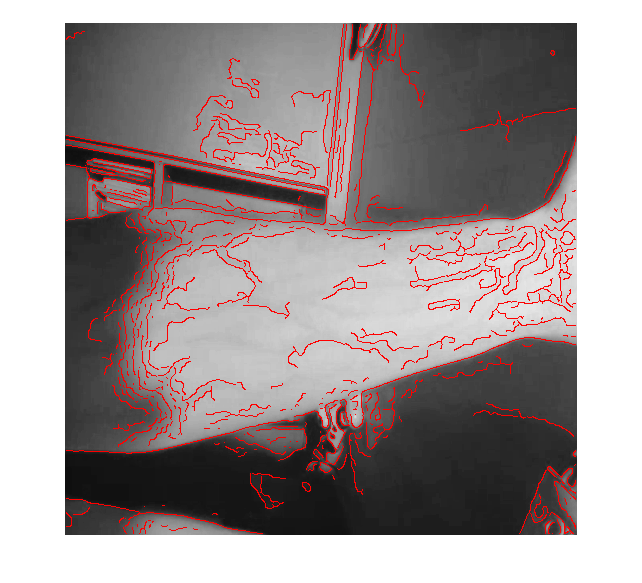

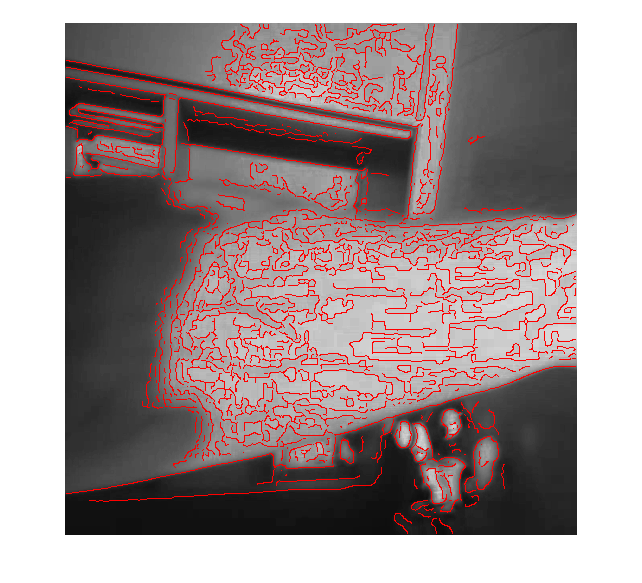

for i = 1:numel(images)
    im = imresize(prcd_ims{i}, resize);
    lines = line_array{i};
    overlay = imoverlay(im, lines, 'red');
    figure, imshow(overlay);
end

#### Postprocessing

% TODO:

% dilate - along lines
dim = 2;

for i = 1:2*(dim-1)
    
    se = zeros(dim);
    if i <= dim
        se(1, i) = 1;
        se(dim, dim+1-i) = 1;
    else
        se(i+1-dim, dim) = 1;
        se(2*dim-i, 1) = 1;        
    end
    
    im_close = imclose(lines, se);
end

## Vein Selection

% TODO:
 
% Select veins
min_len = 0;

veins = false(im_size);
for region = bwconncomp(im_close).PixelIdxList

    if numel(region{1}) < min_len
        continue
    end
    
    [y, x] = ind2sub(im_size, region{1});
    
    for i = 1:size(x,1)
        veins(y(i), x(i)) = 1;
    end
    
%     hold off, imshow(lines), hold on   
%     plot(x, y, 'xr'), pause(0.1)
end

## Visualize

% % Visualize
% fig1 = figure;
% imshow(im_crop), title('Gray, Cropped'), hold on
% imwrite(im_crop, strcat("output/", string(ids(1)), "gray.png"), 'png')

% fig2 = figure;
% imshow(overlay), title('Roberts lines'), hold on
% imwrite(overlay, strcat("output/", string(ids(1)), "roberts.png"), 'png')

% %big cheating here :)
% mask = ones(im_size);
% mask(1:15,:) = 0;
% mask(370:end,:) = 0;
% mask(:,1:45) = 0;
% mask(:,160:end) = 0;

% veins = veins .* mask;
% im_veins = imoverlay(im_gray, veins, 'blue');
% imshow(im_veins)

% fig3 = figure;
% imshow(im_veins), title('Vein Detection'), hold on
% imwrite(im_veins, strcat("output/", string(ids(1)), "veins.png"), 'png')

## Save

% % % Convert to images
% vid = read('vid.mpa'); % load video
% for i = 1:size(vid, 4)
%     frame = vid(:,:,:,i); 
%     imwrite(frame, strcat(string(i), ".png"), 'png')
% end